# **Cluster analysis, a case study **

**All functions coded for this analysis can be seen at the end of the document.**

We load countrydata features and targets.

%Initialize the rng generator
rng('default')
%Load the dataset
format shortG
labels = {'Child mortality','Exports','Health','Imports','Income','Inflation','Life expectancy','Total fertility','Gdpp'};
data =load('data_country.mat') ;
countries = data.country;
features = data.Countrydata;
size(features)

ans =    167     9


size(countries)

ans =    167     1


We have *9* different features in our feature vector and the dataset consists of *167* countries. The features, in numerical order, are:

- **Child mortality**: Death of children under 5 years of age per 1000 live births.  

- **Exports**: Exports of goods and services per capita. Given as %age of the GDP per capita. 

- **Health**: Total health spending per capita. Given as %age of GDP per capita. 

- **Imports**: Imports of goods and services per capita. Given as %age of the GDP per capita.  

- **Income**: Net income per person. Reflects the amount of disposable income that individuals have available to spend or save in monetary terms.

- **Inflation**: The measurement of the annual growth rate of the Total GDP. 

- **Life expectancy**: The average number of years a new born child would live if the current mortality patterns are to remain the same. 

- **Total fertility**: The number of children that would be born to each woman if the current age-fertility rates remain the same. 

- **GDPP**: The GDP per capita (Calculated as the Total GDP divided by the total population) is a measure of the economic output of a nation per person expressed in monetary terms. 

**REMARKS:**

Based on their description these features can be loosely categorized into two groups:

Socio-economic features:

- Exports

- Imports

- Income

- Inflation

- GDP per capita

Health features:

- Child mortality

- Health spending per capita

- Life expectancy

- Total Fertility

**Goal:**

The objective of this study is to cluster the countries using socio-economic and health factors that determine the overall development of the country and to characterize each

resulting cluster (and, consequently, the countries it comprises) based on the relevant values of the above factors.

In order to proceed with the best approach to our goal we first need to extract important info from our dataset for each feature,this includes the following: 

Feeling the Data: 

- Existence of missing values   

- Finding  the max, min,value range, mean, median and standard deviation .

- Approximating and visualizing the probability density function (PDF).

- Outlier Detection.

- Standard score normalizatio

- Minmax feature scaling normalization

- Discovering possible linear dependence with other features.

Feature selection/transformation:

- Which features will be selected for representing each country?

- Will any feature transoformation help us achieve our goal?

Afterwards a reasonable clustering algorithm should be chosen, executed and it's results examined and characterized.

# **Feeling the data**

In this section of the notebook we attempt to extract critical information from the data which will then help us to perform reasonable feature selection/transformation.

First of all we check if our dataset contains any missing values.

%Our dataset contains no missing values
sum(ismissing(features))

ans =      0     0     0     0     0     0     0     0     0


All of the features in the description are continuous valued and positive, with the exception of Inflation, which can also be negative. Child mortality ranges from 0 to 1000 and represents an average rate. Exports, Imports, and Health spending are all expressed as a percentage of GDPP, which means they can take any value from 0% to 100%. Income and GDPP are expressed in monetary terms and are therefore continuous. Life expectancy is expressed through an  average age and is continuous. Total fertility represents the average number of births a mother has in each country and is therefore continuous. Lastly, Inflation can take any value, including negative, and represents a rate of change, so it is also continuous

The min and max value of each feature we use the min and max Matlab functions. We present the respective country that hold the minimum and maximum values for each feature.

%Min Values with the respective country that holds each value
[Min_value,Min_Index] = min(features);
[countries(Min_Index)' ; labels(1:9) ;  num2cell(Min_value)]

ans = 3×9 cell array
    {'Iceland'        }    {'Myanmar'}    {'Qatar' }    {'Myanmar'}    {'Congo Dem Rep'}    {'Seychelles'}    {'Haiti'          }    {'Singapore'      }    {'Burundi'}
    {'Child mortality'}    {'Exports'}    {'Health'}    {'Imports'}    {'Income'       }    {'Inflation' }    {'Life expectancy'}    {'Total fertility'}    {'Gdpp'   }
    {[            2.6]}    {[  0.109]}    {[  1.81]}    {[ 0.0659]}    {[          609]}    {[     -4.21]}    {[           32.1]}    {[           1.15]}    {[    231]}


%Max values with the respective country that holds each value
[Max_value,Max_Index] = max(features);
[countries(Max_Index)' ; labels(1:9) ;  num2cell(Max_value)]

ans = 3×9 cell array
    {'Haiti'          }    {'Singapore'}    {'United States'}    {'Singapore'}    {'Qatar' }    {'Nigeria'  }    {'Japan'          }    {'Niger'          }    {'Luxembourg'}
    {'Child mortality'}    {'Exports'  }    {'Health'       }    {'Imports'  }    {'Income'}    {'Inflation'}    {'Life expectancy'}    {'Total fertility'}    {'Gdpp'      }
    {[            208]}    {[      200]}    {[         17.9]}    {[      174]}    {[125000]}    {[      104]}    {[           82.8]}    {[           7.49]}    {[    105000]}


%Value Ranges
feature_range = Max_value-Min_value;
[labels(1:9) ; num2cell(feature_range)]

ans = 2×9 cell array
    {'Child mortality'}    {'Exports'}    {'Health'}    {'Imports'}    {'Income'}    {'Inflation'}    {'Life expectancy'}    {'Total fertility'}    {'Gdpp'  }
    {[          205.4]}    {[ 199.89]}    {[ 16.09]}    {[ 173.93]}    {[124391]}    {[   108.21]}    {[           50.7]}    {[           6.34]}    {[104769]}


%Means
means = mean(features);
[labels(1:9) ; num2cell(means)]

ans = 2×9 cell array
    {'Child mortality'}    {'Exports'}    {'Health'}    {'Imports'}    {'Income'}    {'Inflation'}    {'Life expectancy'}    {'Total fertility'}    {'Gdpp' }
    {[          38.27]}    {[ 41.109]}    {[6.8157]}    {[  46.89]}    {[ 17145]}    {[   7.7818]}    {[         70.556]}    {[          2.948]}    {[12964]}


%Standard deviation
stdivs = std(features);
[labels(1:9) ; num2cell(stdivs)]

ans = 2×9 cell array
    {'Child mortality'}    {'Exports'}    {'Health'}    {'Imports'}    {'Income'}    {'Inflation'}    {'Life expectancy'}    {'Total fertility'}    {'Gdpp' }
    {[         40.329]}    {[ 27.412]}    {[2.7468]}    {[  24.21]}    {[ 19278]}    {[   10.571]}    {[         8.8932]}    {[         1.5138]}    {[18329]}


%Medians
medians = median(features);
[labels(1:9) ; num2cell(medians)]

ans = 2×9 cell array
    {'Child mortality'}    {'Exports'}    {'Health'}    {'Imports'}    {'Income'}    {'Inflation'}    {'Life expectancy'}    {'Total fertility'}    {'Gdpp'}
    {[           19.3]}    {[     35]}    {[  6.32]}    {[   43.3]}    {[  9960]}    {[     5.39]}    {[           73.1]}    {[           2.41]}    {[4660]}


Since all of are features are continuous we can vizualize all the information from  the mins, max's, value ranges,the means, the medians and the standard devations of each feature by plotting an approximation of their propability density function (PDF). 

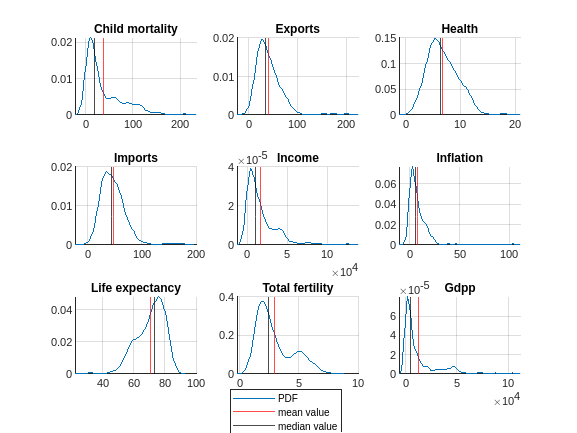

%Since all the features are continuous rather than histograms we can plot the PDF approximation for each feture
%with the mean and median graphed.
figure
for i = 1:9
   subplot(3,3,i)
   grid on
   hold on
   ksdensity(features(:,i)),title(labels(i));
   xline(means(i), 'Color', 'r');
   xline(medians(i), 'Color', 'k');
   hold off
end
legend(["PDF","mean value","median value"])
legend("Position", [0.39866,0.013492,0.19281,0.070439])

**Information derived from the plot:**

Feature value range

- GDPP and Income are in different scales than the rest of the features, Feature scaling will be required

Feature value overlaps

There is overlap between the values of:

- Income and Gdpp 

- Health, Total Fertility, Inflation, Imports, Exports , Child Mortality, Life expectancy

Distribution symmetry:

- Child mortality, exports, Health, Imports, Income, Inflation, Total fertility and Gdpp are positive skewed (the mean is greater than the median). This means that most observations "exist" on the left of the mean.

- Life expectancy is negative skewed (the mean is lesser than the median). This means that most observations "exist" on the right of the mean.

Outlier Detection:

All of out features contain outliers, however GDPP containts the most. This can also be seen from above since its values are mostly grouped near the start of the x axis. Since outliers in our setting  provide countries with extreme cases they are imporant information and we wont drop them.

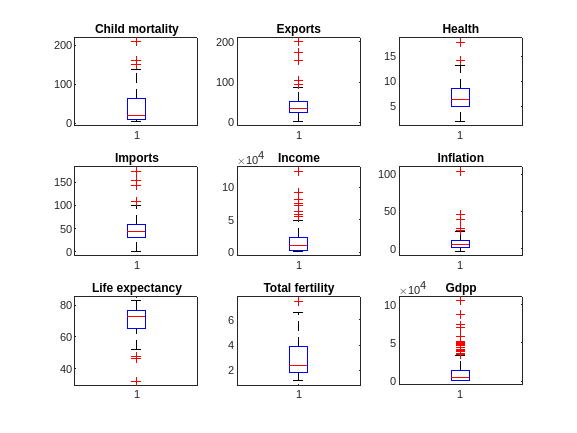

figure
for i = 1:9
   hold on
   subplot(3,3,i)
   boxplot(features(:,i)),title(labels(i));
   hold off
end

Finally we can examine the Pearson correlation coefficient between the features to find possible linear dependencies.

the value of$\rho = \frac{\text{cov}(X,Y)}{\sigma_x \sigma_y}$ for each feature pair is as follows:

correlation_matrix = corrcoef(features);
correlation_matrix_augmented = cat(1,labels,num2cell(correlation_matrix));
temp = ['PAIR' labels];
correlation_matrix_augmented = cat(2,temp',correlation_matrix_augmented)

correlation_matrix_augmented = 10×10 cell array
    {'PAIR'           }    {'Child mortality'}    {'Exports' }    {'Health'  }    {'Imports' }    {'Income'  }    {'Inflation'}    {'Life expectancy'}    {'Total fertility'}    {'Gdpp'    }
    {'Child mortality'}    {[              1]}    {[-0.31809]}    {[ -0.2004]}    {[-0.12721]}    {[-0.52432]}    {[  0.28828]}    {[       -0.88668]}    {[        0.84848]}    {[-0.48303]}
    {'Exports'        }    {[       -0.31809]}    {[       1]}    {[-0.11441]}    {[ 0.73738]}    {[ 0.51678]}    {[ -0.10729]}    {[        0.31631]}    {[       -0.32001]}    {[ 0.41872]}
    {'Health'         }    {[        -0.2004]}    {[-0.11441]}    {[       1]}    {[0.095717]}    {[ 0.12958]}    {[ -0.25538]}    {[        0.21069]}    {[       -0.19667]}    {[ 0.34597]}
    {'Imports'        }    {[       -0.12721]}    {[ 0.73738]}    {[0.095717]}    {[       1]}    {[ 0.12241]}    {[ -0.24699]}    {[       0.054391]}    {[       -0.15905]}    {[  0.1155]}
  

Very significant correlation (>< 0.80) exists between features: 

- Income with GDPP ->  correlation coefficient = 0.89. This makes sense since child mortality and life expectancy should be strongly inversely correlated, meaning that as child mortality decreases, life expectancy increases and vice versa.

- Child Mortality with Life expectency and Total Fertility -> correlation coefficient values = -0.88 and 0.84 respectively.  This makes  since the highest the chance a child wont survive the lower the average life expectancy of this country and the higher the birth rate is, in order to secure some offsprings will survive. 

Significant correlation (>< 0.70) exists between features:

- Total Fertility with Life Expectency ->  correlation coefficient = -0.76 This is to be expected for the same 

- Imports with exports ->  correlation coefficient = 0.73 Since countries with many exports are expected to have enough wealth to import many goods.

Some correlation ( >< 0.60) exists between features:

- Life expectency with income -> correlation coefficient = 0.61 

- Life expectency with GDPP -> correlation coefficient = 0.60  Since both are correlated 

We can graph the scatterplots containing all the combinations of our features to visualize the correlations and gain some extra insight.

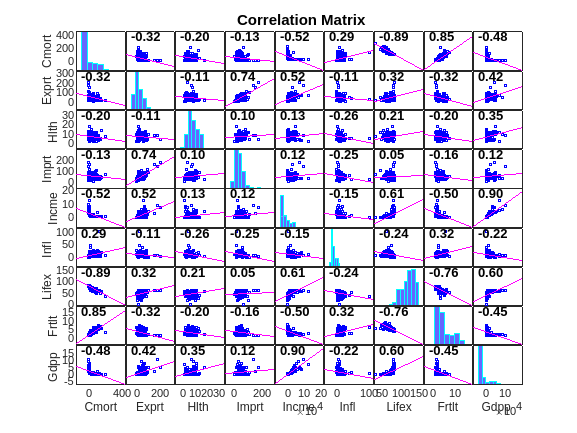

VariableNames = {'Cmort','Exprts','Hlth','Imprts','Incme','Infl','Lifexp','Frtlt','Gdpp'};
figure
corrplot(features, 'varNames',VariableNames)

**IMPORTANT REMARK**

The correlation graph reveals a significant relationship that was not apparent in the correlation table. Many of the feature pair-wise scatter plots show an "L" shape, indicating that there is little or no change in one feature as the other increases until a certain threshold is reached. At this point, the first feature begins to increase rapidly. This dynamic suggests the existence of thresholds in the data. For example, Child Mortality rapidly decreases as income approaches the range of $20,000-$50,000.

# **Feature scaling**

Standardization assumes the feature distributions are Gausian and transorms them so that they have a mean of zero and a standard deviation of one. It is affected much less  by outliers than normalization since there is no predefined range of transformed features.


$$x_{standardized} = \frac{x - \mu}{\sigma}$$


standardized_features = (features - ones(167,1)*means)./(ones(167,1)*stdivs);
standardized_features(1:5,:)

ans =        1.2877      -1.1349      0.27825    -0.082208     -0.80582      0.15686      -1.6142       1.8972     -0.67714
     -0.53733     -0.47822    -0.096725     0.070624     -0.37424     -0.31141      0.64592     -0.85739     -0.48417
     -0.27201    -0.098824     -0.96318     -0.63984     -0.22018      0.78691      0.66841    -0.038289     -0.46398
       2.0018      0.77306      -1.4437     -0.16482     -0.58329       1.3829      -1.1757       2.1218     -0.51472
     -0.69355      0.16019     -0.28603      0.49608      0.10143     -0.59994      0.70215     -0.54032    -0.041692


%Calculating the correlation matrix for the standardized features
stdivs_correlation_matrix = corrcoef(standardized_features);

Normalization, scales the data to a specific range, in our case from 0 to 1. It is affected by outliers as it incorporates them into the 0-1 bound.


$$x_{normalized} = \frac{x - x_{min}}{x_{max} - x_{min}}$$


normalized_features = ((features - ones(167,1)*Min_value))./((ones(167,1)*Max_value - ones(167,1)*Min_value));
normalized_features(1:5,:);
%Calculating the correlation matrix for normalized features
normal_correlation_matrix = corrcoef(normalized_features);

--------

Calculation of the absolute difference between the correlation matrix and the normalized features correlation matrix

%Absolute difference between the correlation_matrix and the normal_correlation_matrix
result_normal = abs(correlation_matrix - normal_correlation_matrix);
sum(result_normal, 'all')

ans =    1.5252e-14


Calculation of the absolute difference between the correlation matrix and the standardized  features correlation matrix

%Absolute difference between the correlation_matrix and the stdivs_correlation_matrix
result_stdiv = abs(correlation_matrix - stdivs_correlation_matrix);
sum(result_stdiv, 'all')

ans =    1.3226e-14


The original correlation matrix before feature scaling is similar to the ones produced after feature scaling. There is a small error, which is likely due to numerical imprecision and does not significantly affect the results. 

- Correlation is preserved, because feature scaling only changes the values of the features, not the relationships between them. In other words, it reduces the range of their values, but the shape of the data is preserved, so the strength and direction of the linear relationship between the features remains unchanged.

Since we want to preserve the outliers of our dataset as much as possible standardization is a  better feature scaling method in our setting.

# Feature selection/transformation

**Feature Selection**

For Feature selection and transformation we investigate the description, the PDFs and the pair-wise correlation coefficient of our features from the previous section.

labels = {'Child mortality','Exports','Health','Imports','Income','Inflation','Life expectancy','Total fertility','Gdpp'};

Socio-economic features

We examine the feature that holds the most information, GDPP with relation to the other socio-economic features. It's equation is:


$$GDPP = \frac{private \ consumption + gross \ private\ investment + government \ investment + government \ spending + (exports – imports)}{country \ population$$
 

- From the equation, we see that the information on exports and imports is directly included in GDP, so we decide to drop these features.

- Income and GDPP have the highest correlation (coefficient of 0.89). This is due to the "private consumption" component in the numerator of GDPP, as higher income per person leads to higher consumption ability. However, since these features contain overlapping information, we decide to drop Income.

- Inflation is a complex feature. Low, stable, and predictable inflation is generally good for a country's economy as it encourages economic activity. However, high inflation can harm the economy by reducing competitiveness in international markets and reducing consumer and business confidence. Therefore, low values of Inflation tend to increase GDPP, while high values tend to decrease it. We find this dynamic relationship interesting and decide to keep the Inflation feature.

Health features:

- Life expectenacy encompasses the information of child mortality in a much less exreme and broad feature. As expected they are extremly correlated, with a correlation coefficient of -0.88. For these two reasons we drop Child Mortality from our Features and keep Life expectency.

- Total fertility is very correlated with Life expecency as mentioned in the previous section ( coefficient of -0.76). However it  holds partial information about population growth which we lack in our setting. For this reason we decide to keep it.

- We keep the Health Spending per Capita feature because it provides information about the amount of money spent on healthcare  in each country, which cannot be extracted from our other features.

REMARK:

High correlation or overlapping information is not always a reason to drop a feature. For example, if we wanted to perform anomaly detection in the feature space of GDPP and Income, outliers might provide interesting information about the distribution of wealth in a country. While we will not pursue this in this analysis, it is an interesting idea for future analysis.

%We drop the columns we mentioned above and split the dataset into our cluster analysis and anomaly detection dataset.
%cluster analysis
selected_features = standardized_features(:,[3 6 7 8 9]);
selected_labels = labels([3 6 7 8 9])

selected_labels = 1×5 cell array
    {'Health'}    {'Inflation'}    {'Life expectancy'}    {'Total fertility'}    {'Gdpp'}


# **Selection of the clustering algorithm(s)**

**In order to select a cost function optimization Clustering algorithm we need to consider:**

- The goal of the analysis.

- The type of representatives .

- The contraint on the $U$ matrix we will place, the $U$ matrix quantifies the relation between the points in our dataset and the clusters.

**Considering the goal of the analysis:**

We want to cluster  each country into a distinct group, where it's representative determines the overall development of the countries in that group. To achieve that we consider the following feature combinations:

- Life expectancy, Total Fertility, GDPP, Health ,Inflation

**Considering the type of representatives** we notice great overlap between the continuous values of both our feature groups, for this reason we expect compact clusters and decide to pick point representatives for our clusters.

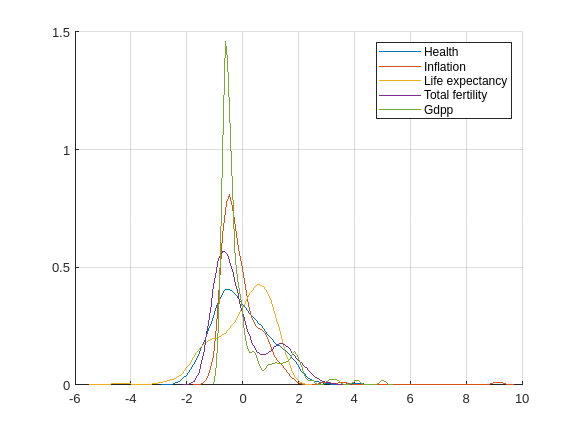

figure
grid on
hold on
for i = 1:5
   ksdensity(selected_features(:,i));
end
hold off
legend(selected_labels(:))

**Considering the constraints on the **$U$**matrix:** We want to categorize countries into distinct groups based on the values of their features. Therefore, we prioritize using a Hard algorithmic scheme, in which each country can only belong to one cluster. If this fails to return reasonable clusters, we may consider other categories of cost function optimization algorithms.

- The k-means clustering algorithm: This can be used if we want to preserve the impact of outliers in our dataset, as the representatives of the clusters (also known as centroids) are vulnerable to extreme feature values in k-means.

- The k-medians algorithm: This can be used for the opposite scenario, where we want to limit the impact of outliers on the cluster representatives.

- The k-medoids algorithm: This can be used if we want to express the cluster representatives as specific countries from our dataset.

Since we dont want to restrict our cluster representatives to be countries from out dataset we drop the k medoids approach. 

Using k means or k medians we can take two approaches. 

- With k means we get represenatives that take into consideration countries with extreme values for our features.

- With k medians we get represenetives that are much less effected  by the extreme values for our features.

We want our  cluster representatives to give an accurate picture for the countries in their cluster, thus our algorithm of choice is k medians.  However to ensure a fair comparison, it is a good idea to continue with both k-means and k-medians, as they offer different approaches to calculating the cluster representatives and will allow us to compare our results.

# **Execution of the clustering algorithm(s)**

### **Optimal cluster number identification**

X = selected_features;

Before proceeding with the execution of the algorithms we need to consider the parameters of our algorithms and a way to select the most accurate ones. For the k-means and k-medians algorithm we have two parameters: 

- the initial cluster representatives

- The number of clusters

To initialize the cluster representatives, we use a function that splits our dataset (size Nxl) into 'm' random partitions and returns 'm' 'lx1' vectors, which correspond to the mean vector of each partition. The function also requires a third parameter, seed_number, which specifies the random seed for shuffling the dataset before partitioning it.

- 'm' corresponds to the number of clusters and the number of initial cluster representatives, for exaple when m=3 and seed_number = 5:

theta_zero_means = mean_reps_init(X,3,5)

theta_zero_means =       0.15302      -0.1651    -0.020472
     0.020028     0.085764    -0.092353
     -0.25548      0.16384     0.095757
      0.18162    -0.098101    -0.094257
    -0.041434      0.12775    -0.069212


**In order to find the number of clusters that approximates the physical clusters that may exist in the feature space we can use the elbow method for different random states of the initial representatives.**

It is based on the comparison of the value of the cost function vs the number of cluster in each iteration of the k means and k medians algorithm as shown below:

$$$J = \sum_{i=1}^{m} \sum_{x \in C_i} ||x - \mu_i||^2$$$ vs Number of clusters.

$$J = \sum_{i=1}^m \sum_{x \in C_j} ||x - \mu_i||^1$ vs Number of clusters 

We expect that the value of the cost function will decrease as the number of clusters 'm' increases, since with more representatives we get a better partitioning of the data. However, when the decrease becomes less significant abruptly, denoted by an "elbow" in the plot, the number of clusters at that point is considered optimal. This is because we have reached convergence, and any further decrease in the cost function will be small.

**Elbow Method**

- We run 5 different random initialized representative matrices for the k means and and k medians algorithms 

- We get the results of the cost function and plot it against the cluster number.

- We discuss the findings

seed_number =     85


Iteration Complete


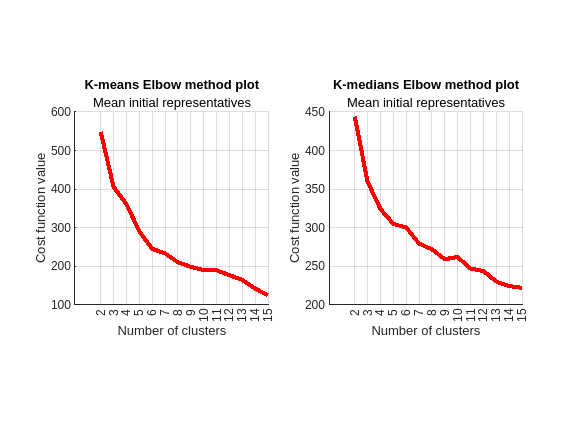

seed_number =    103


Iteration Complete


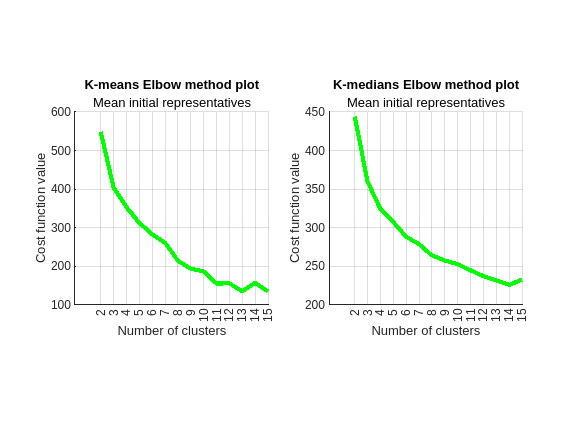

seed_number =    258


Iteration Complete


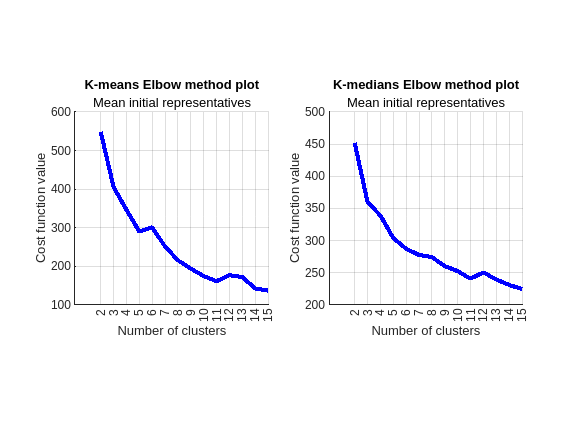

seed_number =    303


Iteration Complete


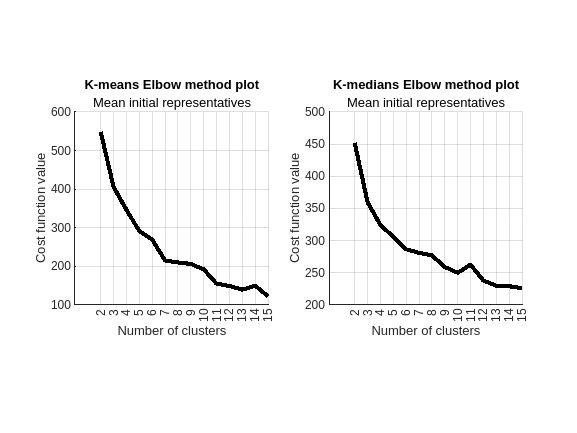

seed_number =    356


Iteration Complete


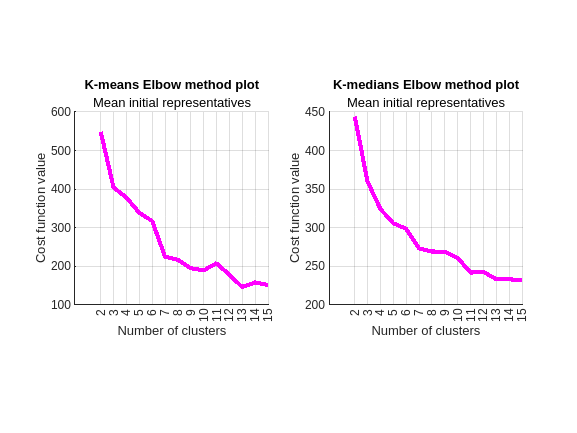

color = ['r','g','b','k','m'];
rnd_seed_array = [];
for i = 1:5
    J_array_means  = [];
    J_array_medians = [];
    m_array = [];
    %plot the figure
    figure
    %set the random seed for initial representatives
    seed_number = randi([1, 400])
    rnd_seed_array = cat(2,rnd_seed_array,seed_number);
    for m = 2:15
         theta_zero_mean = mean_reps_init(X,m,seed_number);
         [~,~, J_means] = k_means(X',theta_zero_mean);
         [~,~,J_medians] = k_medians(X',theta_zero_mean);
         %Add the values to the arrays
         J_array_means = cat(2, J_array_means, J_means);
         J_array_medians = cat(2, J_array_medians, J_medians);
         m_array = cat(2, m_array, m);
    end
    disp('Iteration Complete')
    %kmeans plot
    subplot(1,2,1)
    pbaspect([1 1 1])
    grid on
    xticks(2:m);
    line(m_array,J_array_means,'Color',color(i),'LineWidth',3);
    title('K-means Elbow method plot')
    subtitle('Mean initial representatives')
    ylabel('Cost function value')
    xlabel('Number of clusters')
    %kmedians plot
    subplot(1,2,2)
    pbaspect([1 1 1])
    grid on
    xticks(2:m);
    line(m_array,J_array_medians,'Color',color(i),'LineWidth',3);
    title('K-medians Elbow method plot')
    subtitle('Mean initial representatives')
    ylabel('Cost function value')
    xlabel('Number of clusters')
end

After examining the graphs above, we come to the following conclusions:

- The optimal number of clusters is likely 3, as an "elbow" is seen there in all plots.

- Cluster numbers 6-7 are also possible optimals, as "elbows" are spotted there on average according to the plots.

However, in all cases, the "elbows" are not sufficiently defined, so we cannot be confident in our choice of cluster number using this method. This may be due to the fact that the value of the cost function does not decrease significantly enough at these points to clearly indicate convergence. Therefore, we may need to consider other methods to determine the optimal number of clusters.

**For this reason we consider a second evaluation method, the Silhouette Method**

The silhouette method is used to provide  a measure of the compactness and separation of clusters in a dataset. It is defined as the difference between the average distance of a point to other points in its own cluster and the average distance of the point to points in the nearest neighboring cluster, normalized by the maximum of these two values. Mathematically, it can be written as:


$$$s(i) = \frac{b(i) - a(i)}{\max(a(i), b(i))}$$$


where $$a(i)$$ is the average distance of point $$i$$ to other points in its own cluster and $b(i)$ is the average distance of point $$i$$ to points in the nearest neighboring cluster. The silhouette value $s(i)$ for each point ranges from -1 to 1, with values close to 1 indicating a well-separated cluster and values close to -1 indicating a poorly separated or overlapping cluster.

We run this method:

- With the same 5 different random initialized representative matrices for the k means and and k medians algorithms 

- We get the shiluette coeficients and plot the results for increasing cluster numbers 2 - 7.

- We discuss the findings

**Silhouette Method for K means**

ans = 'Random seed value: 85'

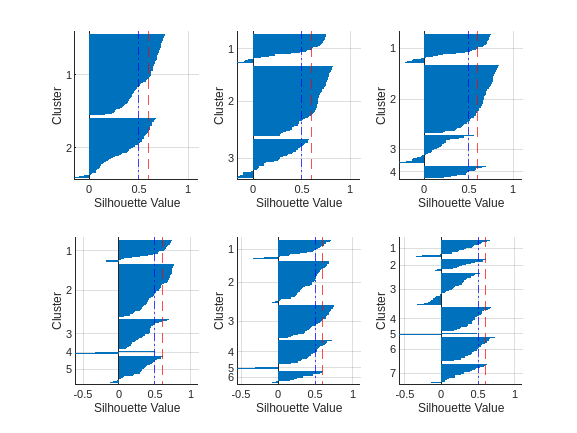

ans = 'Random seed value: 103'

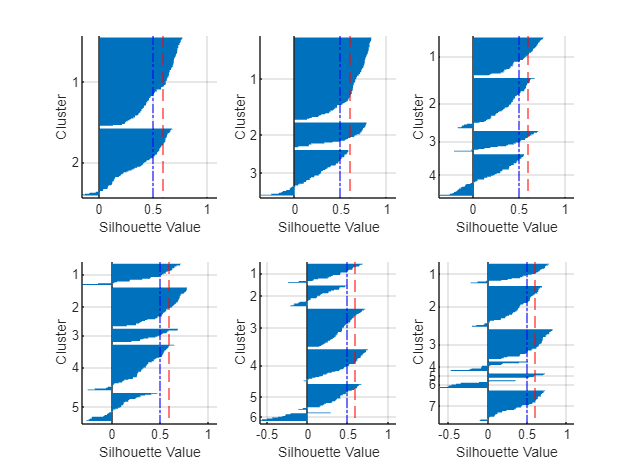

ans = 'Random seed value: 258'

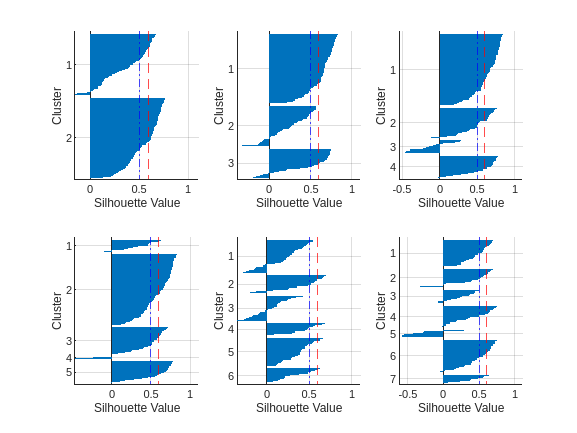

ans = 'Random seed value: 303'

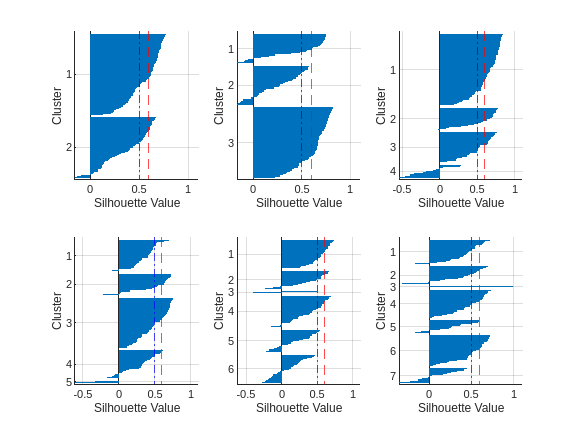

ans = 'Random seed value: 356'

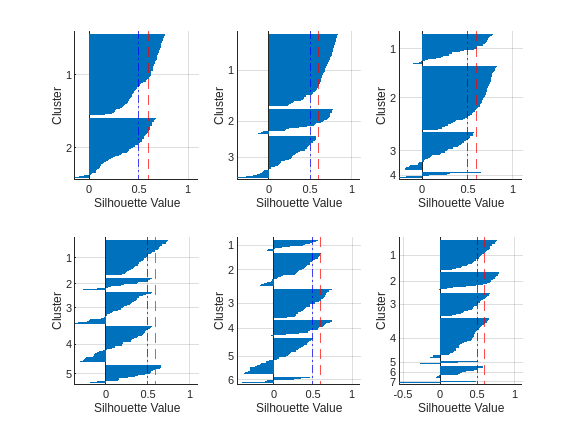

theta_means_cell = {};
for i = 1:5
    rng(rnd_seed_array(i))
    sprintf('Random seed value: %d', rnd_seed_array(i))
    figure
    bel_array = [];
    %plot the figure
    %set the random seed
    for m = 2:7
         subplot(2,3,m-1);
         theta_zero_mean = mean_reps_init(X,m,rnd_seed_array(i));
         [theta,bel, ~] = k_means(X',theta_zero_mean);
         cat(2,bel_array,bel);
         %Add the values to the arrays
         theta_means_cell{end+1} = theta;
         grid on
         xline(0.6, 'Color', 'r',LineStyle='--');
         xline(0.5, 'Color', 'b',LineStyle='-.');
         hold on
         %We use squared Euclidean distance for the metric since it is the
         %distance that kmeans utilizes
         silhouette(X,bel,'sqEuclidean')
         hold off
    end
end

**Silhouette Method for K medians**

ans = 'Random seed value: 85'

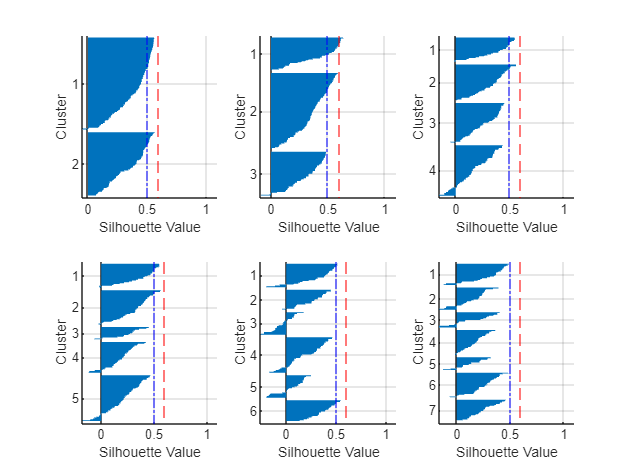

ans = 'Random seed value: 103'

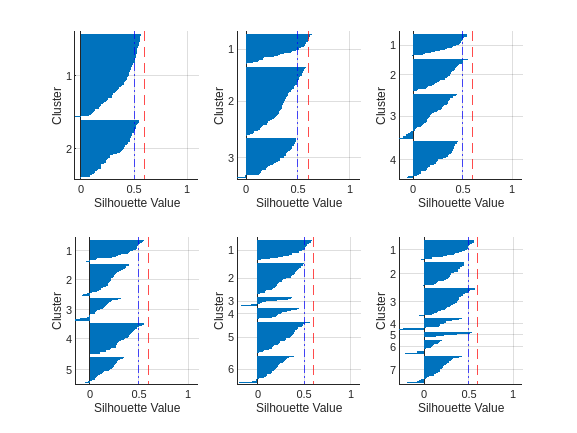

ans = 'Random seed value: 258'

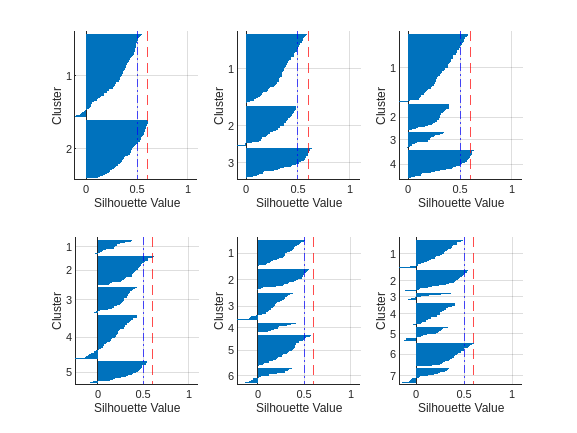

ans = 'Random seed value: 303'

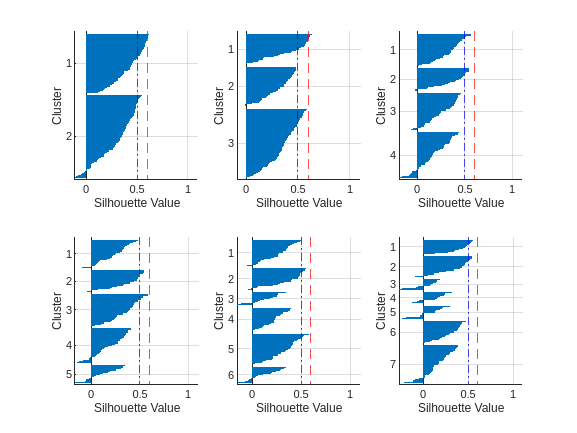

ans = 'Random seed value: 356'

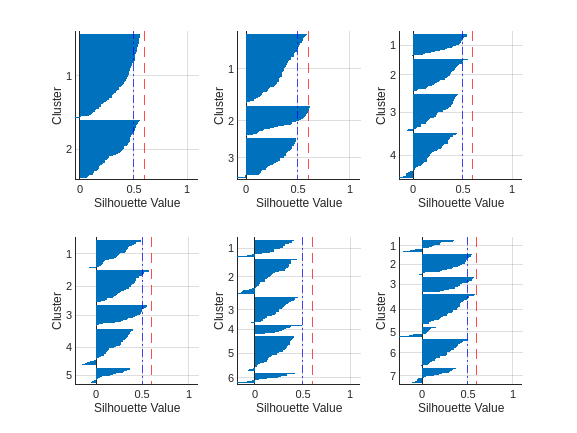

theta_medians_cell = {};
for i = 1:5
    rng(rnd_seed_array(i))
    sprintf('Random seed value: %d', rnd_seed_array(i))
    figure
    bel_array = [];
    %plot the figure
    %set the random seed
    for m = 2:7
         subplot(2,3,m-1);
         theta_zero_mean = mean_reps_init(X,m,rnd_seed_array(i));
         [theta,bel, ~] = k_medians(X',theta_zero_mean);
         cat(2,bel_array,bel);
         %Add the values to the arrays
         theta_medians_cell{end+1} = theta;
         grid on
         xline(0.6, 'Color', 'r',LineStyle='--');
         xline(0.5, 'Color', 'b',LineStyle='-.');
         hold on
         %We use Manhatan distance for the metric since it is the one that
         %kmedians utilizes
         silhouette(X,bel,'cityblock')
         hold off
    end
end 

Considering the results of the shilouete method we observe: 

- According to the silhouette method, 2 clusters also appear to be an optimal choice. However, we do not want to limit the information of a 5-dimensional cluster analysis to such a small number of clusters if a bigger optimal cluster numbers exist.

- As we move above 3 clusters while we dont always have a substuntial increase in overlapping points between clusters, their seperation values are generally lower and their shape is affected much more by the different initial representatives.

- Thus with the shilouete method we can verify that 3 is the optimal cluster number since it consinently, again, no matter the initial representatives provides clusters with points that are on average well-separated ( have the highest silhouete values on average for each cluster)  and less overlapping clusters (have lower silhouette values on average for points within the same cluster).

- Additionally K medians tends to seperate the clusters better with less overlap. This solidifies K medians as our algorithm of choice.

### Execution of the clustering algorithm

Having decided on the optimal cluster number we execute k medians for the selected features of our dataset with the random seed that intialized the representatives with the best clustering results for k medians, seed  `303`:

selected_labels

selected_labels = 1×5 cell array
    {'Health'}    {'Inflation'}    {'Life expectancy'}    {'Total fertility'}    {'Gdpp'}


features_final = standardized_features(:,[3,6,7,8,9]);
X = features_final';
%feature_dimensions
feature_dims = size(X,1);

Before presenting our clustering results.

In order to determine which features contribute the most to the decision of the clusters we juxtapose pairwise the clustered features of the 5 dimensional clustering with the 2 dimensional clustering using 3 cluster representatives. In the first case the cluster representatives are denoted as squares, while in the second case as crosses.

We expect to see the following plots:

1-2   :health-inflation

3-4   :health-life expectancy

5-6   :health-total fertility

7-8   :health-gdpp

9-10  :inflation-life expectancy

11-12 :inflation-total fertility

13-14 :inflation-gdpp

15-16  :life expectancy-total_fertility

17-18  :life expectancy-gdpp

9-20  :gdpp-total_fertility

%This code encodes the feature into an array for pairwise combinations and
%readies them to be passed into the k medians algorithm

encoded =[];
features_combinations = [];
for i=1 : feature_dims
    for j=1 :feature_dims
        if((i~=j) & ( ~any(encoded==i*j )))
            encoded=[encoded,(i*j)];
            features_combinations = [features_combinations,features_final(:,[i,j])] ;
        end
    end
end
%create cellarray of string titles where each title is one element in the array
feature_titles = cellstr(["health-inflation";"health-life expectancy";"health-total fertility";"health-gdpp";"inflation-life expectancy";"inflation-total fertility";"inflation-gdpp";"life_expectancy-total fertility";"life expectancy-gdpp";"total fertility-gdpp"])';
% We set up a pointer to give the algorithm to our function call.
s2 = @k_medians;
% also pass the names to the plotting function
Name2=func2str(s2) ;


%with this function we run the clustering on all features and then plot the pairwise combinations of the results (plot pairs)
% give all features (5 x 167 )
features_final = features_final';

As mentioned we use 3 reprsentatives and the random seed of `303 to perform clustering in 5 feature dimensions`.

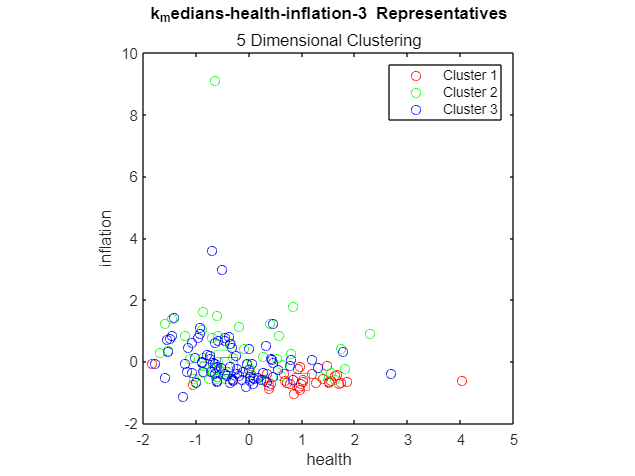

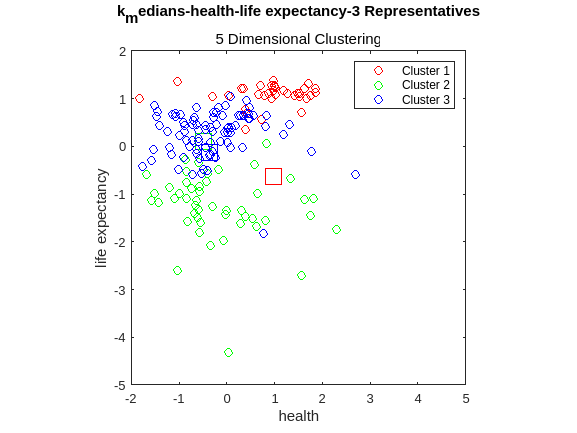

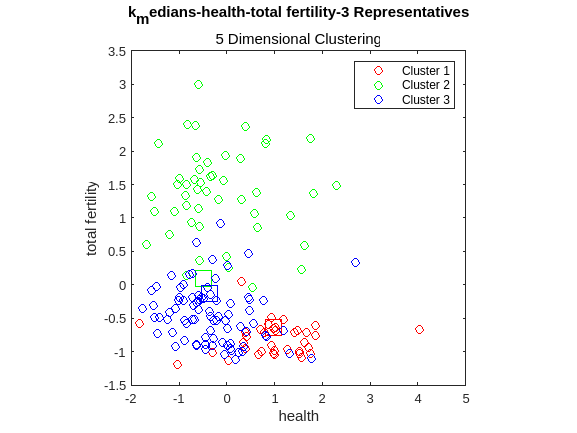

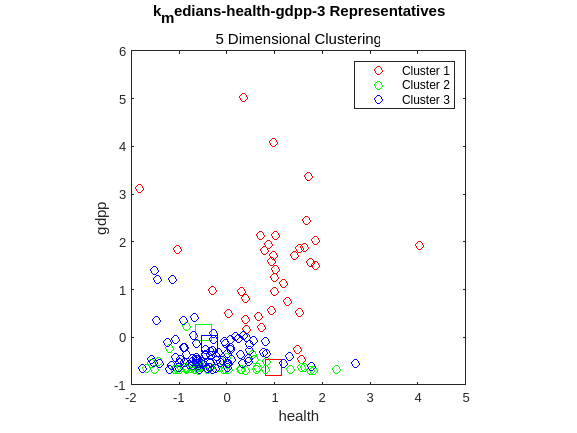

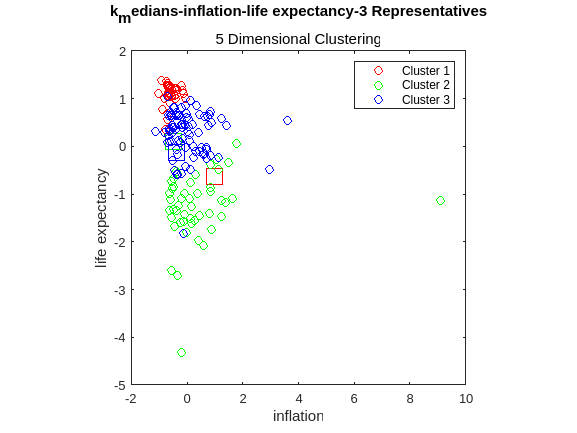

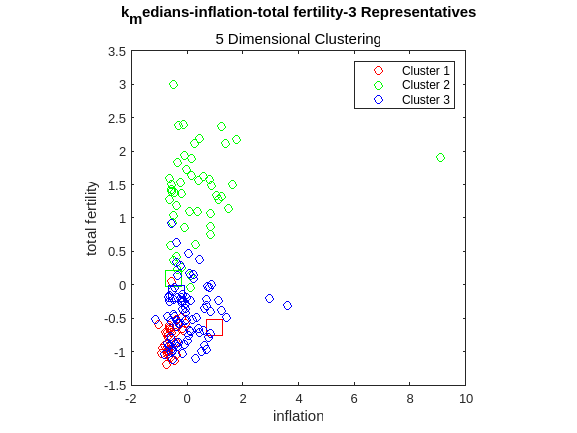

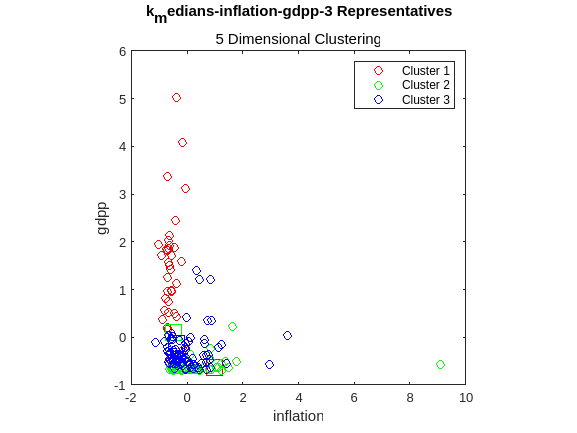

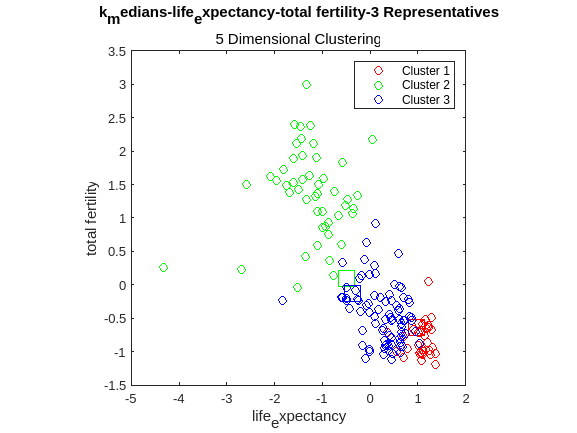

feature_number = 3;
start_cluster_num =3;
end_cluster_num = 3;
% We the seed that corresponds to the best clustering results , derived
% from the previous section.
seed_number = 303;

%This function carries out the clustering in 5 dimensions and plots the
%features pairwise
[theta1,bel1,J1] = LoopAlgorithmAllfeatures(features_final, start_cluster_num, end_cluster_num,features_combinations,Name2,s2,feature_number,feature_titles,seed_number);

feature_number = 2;

Now we present the 2 dimensional clustered pairwise feature combinations:

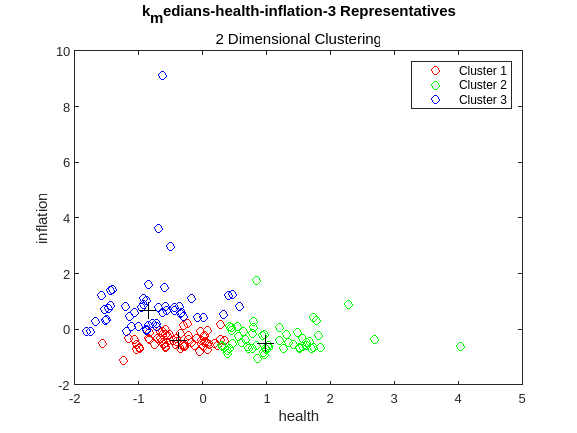

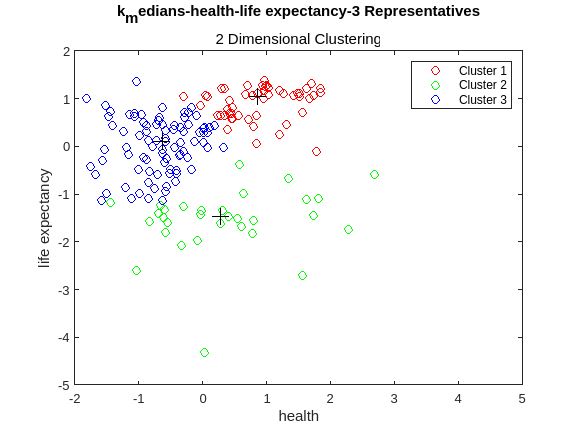

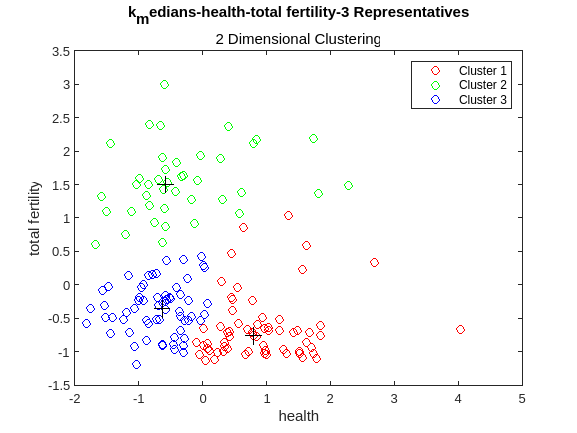

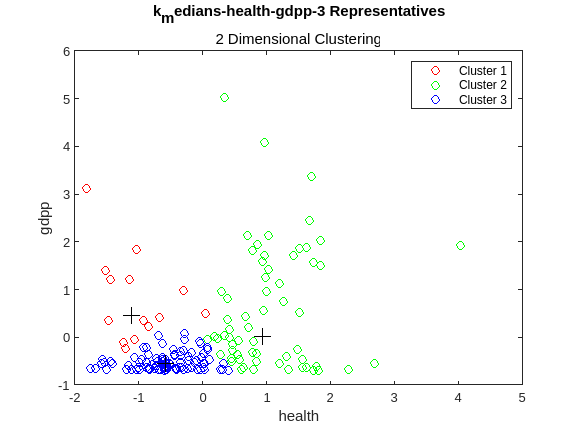

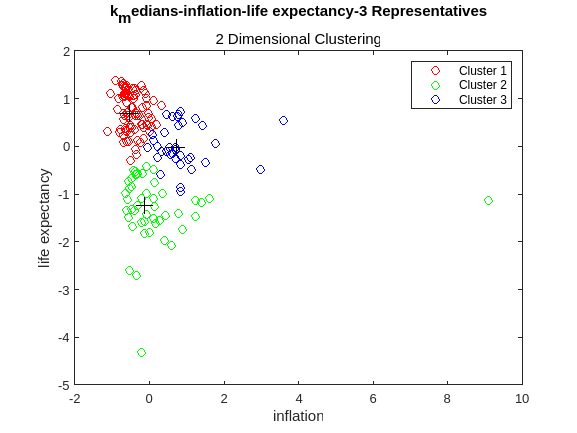

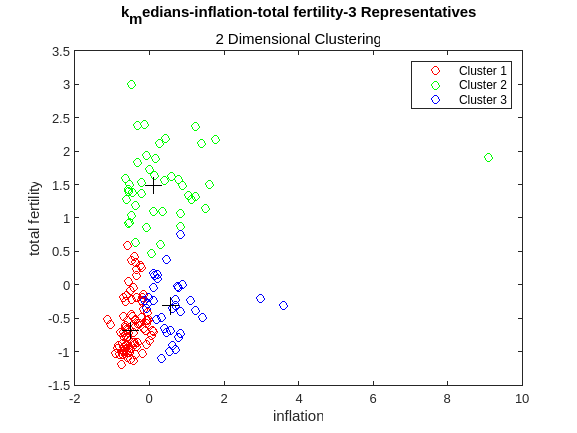

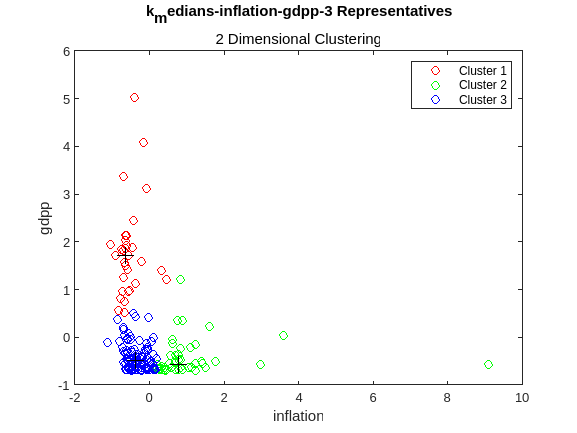

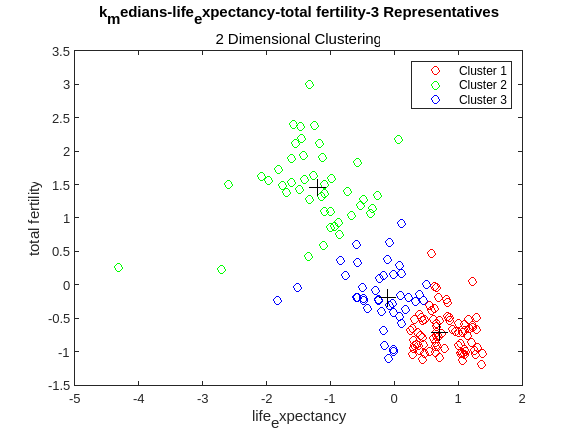

%This function carries out the clustering in 2 dimensions and plots the
%features pairwise
[theta2,bel2,J2] = LoopAlgorithmPicker2(start_cluster_num,end_cluster_num,features_combinations,Name2,s2,feature_number,feature_titles,seed_number);

 By comparing each 5 dimensional clustered pair with its corresponding 2 dimensional,  we can see that the shape of the clusters is generally preserved in: 

- Life expectancy-health

-  Total fertility- health 

- Gdpp -life expectancy 

- Total fertility - inflation 

- Gdpp - total fertility 

This means that these features pairs have strong relationships, this means that contribute vastly into the clustering results and the shape of their clusters is preserved even in higher dimensions. While Inflation and Health in 5 dimensions have the "worst" clustering ability, this is probably due to the fact that their relationship is not that strong and it is overcome by the relationships of other features in higher dimensions. 

# **Characterization of the clusters**

Having completed the execution of the clustering algorithm, the final three cluster representatives  are:

cell2table(cat(2,selected_labels',num2cell(theta1(:,[1 2 3]))),'VariableNames',{'Features','Representative 1','Representative 2','Representative 3'})

ans = 5×4 table
         Features          Representative 1    Representative 2    Representative 3
    ___________________    ________________    ________________    ________________

    {'Health'         }         0.98088            -0.48626            -0.36613    
    {'Inflation'      }        -0.63963             0.10152            -0.13545    
    {'Life expectancy'}           1.107             -1.1588             0.35356    
    {'Total fertility'}        -0.82106              1.3918            -0.47426    
    {'Gdpp'           }          1.5405            -0.65647            -0.43015    


We split our country labels and feature vectors to their corresponding clusters, that match the ones in the 5 dimensional, pairwise feature plots presented in the previous section.

%find the index of each data vector that corresponds to each cluster 
k1 = find(bel1 == 1);
k2 = find(bel1 == 2);
k3 = find(bel1 == 3);
%index the countries 
countries_1 = countries(k2,:);
countries_2 = countries(k1,:);  
countries_3 = countries(k3,:); 
%index the feature vectors
X_1 = X(:,k2)';
X_2 = X(:,k1)';
X_3 = X(:,k3)';

We find the mean and standard deviation of each feature for each corresponding cluster:                   

Cluster 1:

selected_labels

selected_labels = 1×5 cell array
    {'Health'}    {'Inflation'}    {'Life expectancy'}    {'Total fertility'}    {'Gdpp'}


cluster_1_means = mean(X_1)

cluster_1_means =      -0.16711      0.38329      -1.2521       1.3628     -0.60805


cluster_1_stdv = std(X_1)

cluster_1_stdv =       0.95789       1.4569      0.71574      0.65988      0.15396


Cluster 2:

selected_labels

selected_labels = 1×5 cell array
    {'Health'}    {'Inflation'}    {'Life expectancy'}    {'Total fertility'}    {'Gdpp'}


cluster_2_means = mean(X_2)

cluster_2_means =       0.96551     -0.58843        1.076      -0.8117        1.501


cluster_2_stdv = std(X_2)

cluster_2_stdv =       0.94129      0.21483      0.22104       0.2413       1.1445


Cluster 3:

selected_labels

selected_labels = 1×5 cell array
    {'Health'}    {'Inflation'}    {'Life expectancy'}    {'Total fertility'}    {'Gdpp'}


cluster_3_means = mean(X_3)

cluster_3_means =      -0.32213     0.033562      0.25738     -0.43606     -0.29939


cluster_3_stdv = std(X_3)

cluster_3_stdv =       0.76789       0.7409       0.4657      0.42552      0.39431


We find the standard deviation of each corresponding cluster is:

We characterize each one of them, based on the values of the features that are encountered among the vectors of each cluster, comparing them with the origical feature distribution before the clsutering. 

This relationships can be seen by plotting the aprroximate probability density functions for each feature in each cluster. The probability density functions for each feature of the non clustered dataset is:

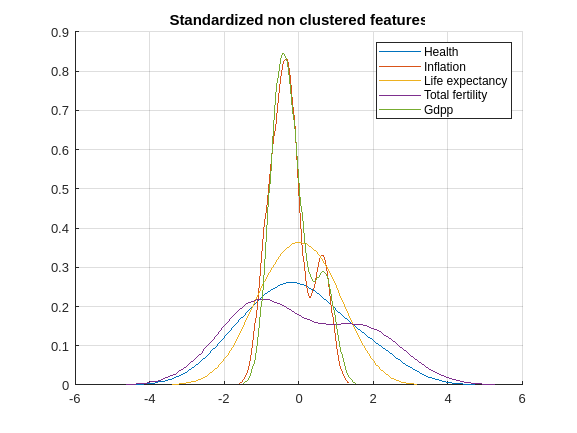

figure
title('Standardized non clustered features')
grid on
hold on
for i = 1:5
   ksdensity(X(:,i));
end 
hold off
legend(selected_labels(:))

**We employ a discrete  scale to characterize the changes in standard  and mean values for each cluster compared to the original feature distributions of the dataset, which were standardized and thus have a standard deviation of 1 and a mean of 0:**

- very small change: 0.00 - 0.20

- small change : 0.20 - 0.40

- medium change : 0.40 - 0.60

- big change : 0.60 - 0.80

- very big change: 0.80 - 1.00

- extreme change: 1.00 +

**Cluster 1:**

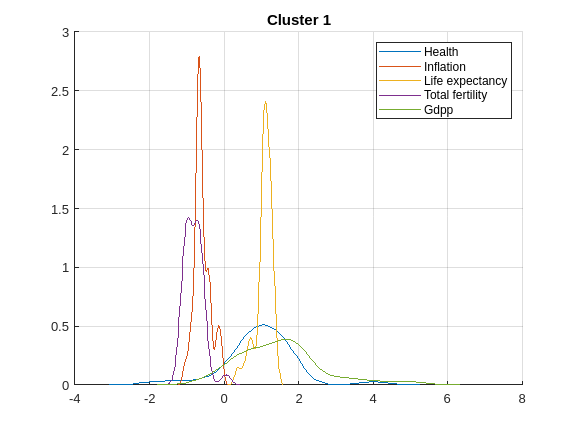

figure
title('Cluster 1')
grid on
hold on
for i = 1:5
   ksdensity(X_2(:,i));
end
hold off
legend(selected_labels(:))

- Health:  very small negative change in standard deviation, big positive change in the mean value. (spread of values that produce a big mean value increase)

- Inflation: big negative change in standard deviation, medium negative change in the mean value. (concentration of values with a medium mean  value decrease)

- Life expectancy: big negative change in standard deviation, extreme positive change in the mean value. (concetration of values with an exreme mean value increase)

- Total Fertility: big negative change in standard deviation, with a very big negative change in the mean value. (concetration of values with a very big mean decrease)

- GDPP: has a very small positive change in standard deviation, extreme positive change in the mean value. (spread of values that produce an exreme mean value increase)

Thus the cluster is moslty characterized by countries with:

- Extremly high on average but spreaded out values of GDPP, with possible outliers.

- Very very low Total fertility across all of them.

- Very low inflation across all of them.

- Extremely high Life expectancy across all of them.

And secondly by:

-  Lower than averge health spending.

**Cluster 2:**

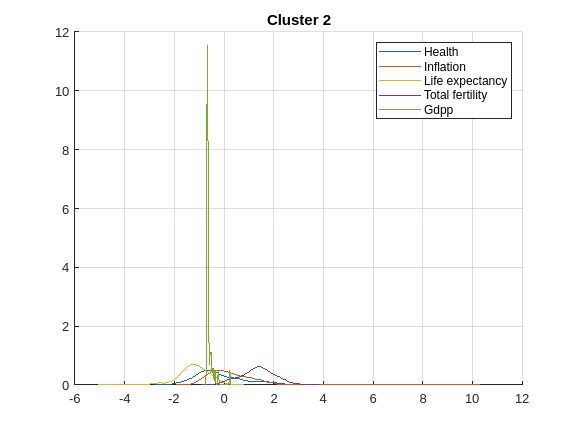

figure
title('Cluster 2')
grid on
hold on
for i = 1:5
   ksdensity(X_1(:,i));
end 
hold off
legend(selected_labels(:))

- Health: very small negative change in standard deviation, very  small negative change  in the mean value. (spread of values that produce a very small mean value decrease)

- Inflation: medium  positive change in standard deviation,  small positive change in the mean value. (spread values that produce a small mean value increase)

- Life expectancy: small negative change in standard dedeviation, extreme negative change in the mean value. (spread of values that produce an extreme mean value decrease)

- Total fertility: medium negative change in standard deviation, extreme postive change in the mean value. (spread of values that produce an extreme mean value increase)

- GDPP: very big negative change in standard deviation, big negative change in the mean value. (concetration of values with an big mean value decrease)

Thus the cluster is moslty characterized by countries with:

- Very low GDPP across all of them.

- Extremly low life expectation in   in many of them.

- Etremely high total fertility  in most of them.

And secondly by:

- higher than average Inflation  but with a big spread of values.

- Lower than averge health spending, same as inflation , spreaded out.

**Cluster 3: **

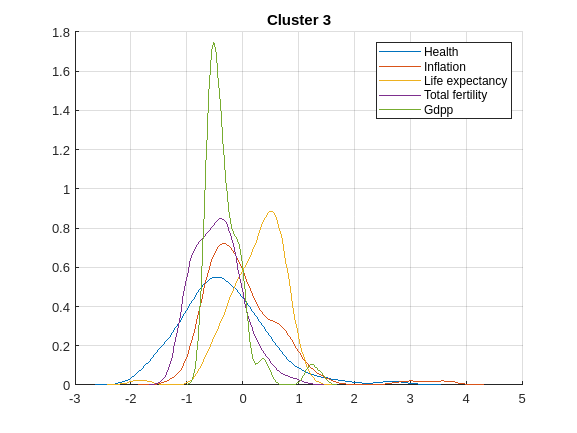

figure
title('Cluster 3')
grid on
hold on
for i = 1:5
   ksdensity(X_3(:,i));
end
hold off
legend(selected_labels(:))

- Health: very small negative change in standard deviation, small  negative change in the mean value. (spread of values that produce a small mean value decrease)

- Inflation: Has a small negative  change in standard deviation, almost no change in the mean value (spread out values with no affect on the mean)

- Life expectancy: Has a medium negative change in standard  deviation, small positive change in its mean. (medium spread that produce a small mean value increase)

- Total fertility: Has a medium negative change in standard deviation, medium positive change in its mean.  (medium spread that produce a medium mean value increase)

- GDPP: Has a big negative standard deviation change and  small negative change in its mean.(concetrated values that produce a small mean value decrease)

Thus the cluster is moslty characterized by countries with:

-   Countries with lower than average GDPP  across all of them

-   Higher than average life expectancy across most of them 

-   Above average Total fertility across most of them 

And secondly by:

-   High Health spending with spread out values, containing possible outliers.

### **RESULTS **

Comparing the 3 clusters we can clearly see that the features: life expectancy and total fertility are inversely proportional in cluster **1** , whereas inflation is low compared to the other two clusters. By observing this pattern we can be more confident that this cluster corresponds to countries with higher quality of life but with less people determined to have children.This can be probably linked to many other socioeconomic and psychological factors  which are out of the scope of the present work. The health feature is also higher than on the other clusters but has a big  standard deviation , which does not a present clear view about cluster **1** since those countries can have different political structure ,public and private sector thus health spending can be influenced by many different factors. Gdpp is also higher in cluster **1** ,which is in accordance with the assumption thath cluster **1 **presents the more developed countries ,since higher gdpp is linked with general higher economy level .Inflation is also very low for cluster **1** further establishing that cluster **1** presents countries more developed in contrast to countries of cluster **2** and cluster **3**.  

- Thus Cluster **1 **corresponds to highly developed countries.

In contrast to cluster **1** , in cluster **2** we observe much lower gdpp values with also smaller deviations.Much bigger inflation is also characteristic for this cluster as well as smaller health spending. Altough more important factors than health  are the much bigger total fertility and the very low life expectancy. These  two features together usually can be a sign of underdeveloped countries with very high birth rate but low quality of life and economy. This idea can further be strengthened by the low GDPP as previously stated and by the big inflation as well , usually presented in countries with political and economical instability. 

-  Thus Cluster **2** corresponds to underdeveloped countries.

Finally we take a look at cluster **3** where all the features are generally more spread and with big deviations. Starting from health spending we can see that there is not clear pattern like in cluster **1 **meaning that this feature alone can not present a clear view about the cluster .The same can be said about inflation which also has a generally big range of possible values. Life expectancy and GDP are higher than cluster **2** and lower than cluster **1 **.Combining this with the fact that this cluster also presents relatively low to medium total fertility we get  a more clear view of this cluster Specifically this cluster probably depicts countries that are not as developed as the countries in cluster **1** but have a better quality of life than countries in cluster **2**. 

- Thus Cluster **3 ** corresponds to countries with  medium development. 

The clustering seems to distinguish the developed (cluster **1**) and underdeveloped countries (cluster **2**) by account of their sharp differences in the feature space , which can be also verified by the mean and standard deviations of their features. Furthermore between those extremely different clusters comes cluster **3** ,which most likely groups together those countries that are in between those two extremities. 

Finally we present the countries that belon in each cluster: 

rep_result = cat(2,selected_labels',num2cell(theta1(:,[1 2 3])));
rep_result = cell2table(rep_result,"VariableNames",{'Feaures', 'Cluster 1', 'Cluster 2','Cluster 3'})

rep_result = 5×4 table
          Feaures          Cluster 1    Cluster 2    Cluster 3
    ___________________    _________    _________    _________

    {'Health'         }     0.98088     -0.48626     -0.36613 
    {'Inflation'      }    -0.63963      0.10152     -0.13545 
    {'Life expectancy'}       1.107      -1.1588      0.35356 
    {'Total fertility'}    -0.82106       1.3918     -0.47426 
    {'Gdpp'           }      1.5405     -0.65647     -0.43015 


array2table(countries_2,"VariableNames",{'Developed countries / Cluster 1'})

ans = 36×1 table
    Developed countries / Cluster 1
    _______________________________

      {'Australia'             }   
      {'Austria'               }   
      {'Bahamas'               }   
      {'Barbados'              }   
      {'Belgium'               }   
      {'Bosnia and Herzegovina'}   
      {'Canada'                }   
      {'Costa Rica'            }   
      {'Cyprus'                }   
      {'Czech Republic'        }   
      {'Denmark'               }   
      {'Finland'               }   
      {'France'                }   
      {'Germany'               }   
      {'Greece'                }   
      {'Iceland'               }   


array2table(countries_1,"VariableNames",{'Underdeveloped countries / Cluster 2'})

ans = 48×1 table
    Underdeveloped countries / Cluster 2
    ____________________________________

        {'Afghanistan'             }    
        {'Angola'                  }    
        {'Benin'                   }    
        {'Botswana'                }    
        {'Burkina Faso'            }    
        {'Burundi'                 }    
        {'Cameroon'                }    
        {'Central African Republic'}    
        {'Chad'                    }    
        {'Comoros'                 }    
        {'Congo Dem Rep'           }    
        {'Congo Rep'               }    
        {'Cote d'Ivoire'           }    
        {'Equatorial Guinea'       }    
        {'Eritrea'                 }    
        {'Gabon'                   }    


array2table(countries_3,"VariableNames",{'Medium development countries / Cluster 3'})

ans = 83×1 table
    Medium development countries / Cluster 3
    ________________________________________

            {'Albania'            }         
            {'Algeria'            }         
            {'Antigua and Barbuda'}         
            {'Argentina'          }         
            {'Armenia'            }         
            {'Azerbaijan'         }         
            {'Bahrain'            }         
            {'Bangladesh'         }         
            {'Belarus'            }         
            {'Belize'             }         
            {'Bhutan'             }         
            {'Bolivia'            }         
            {'Brazil'             }         
            {'Brunei'             }         
            {'Bulgaria'           }         
            {'Cambodia'           }         


**Comments on the effect of representative number in this clustering case:**

By observation of the cluster sizes we have captured the two extremes, corresponding to underdeveloped and developed countries while cluster 3 contains countries that are inbetween with respect to development levels. We believe that increasing the representative number would probably split the countries corresponding to Cluster **3** into more clusters thus creating more levels of development for this cluster, while clusters **1** and **2** will remain mostly intact.

# **Functions Used **

### **Functions Coded**

function [theta_zero] = mean_reps_init(X,m,seed_number)
    %This function shuffle the dataset into m random partition,
    %And gets the mean vector of each partition as an initial cluster
    %representative
    %Get the shape of the dataset
    rng(seed_number);
    [N,l] = size(X);
    %initialize the theta_zero matrix 
    theta_zero = zeros(l,m);
    %shuffle the dataset into m random but equal to the closest intiger partitions.
    rand_indices = randperm(N);
    X_shuffled = X(rand_indices,:);
    partition_size = fix(N/m);
    %Add the mean row vector of each partition as a column in the theta_zero matrix.
    count = 1;
    for i=1:m
        temp = X_shuffled(count:(partition_size*i),:);
        theta_zero(:,i) = (mean(temp)');
        count = count + partition_size;
    end
end

-----

function plotClusters(Name,cmap,k,feature_number,bel,theta,X,l,titles,counter)
     %create a colormap set of #colors = #representatives
     figure
     grid on 
     pbaspect([1 1 1]);
     legendEntries = cell(1, k);
     for i=1:k
            plot(X(1,bel==i),X(2,bel==i),'color',cmap(i,:),'marker','o','Linestyle','None')
            s=strcat(Name,'-',titles(counter),'-',int2str(k),' Representatives');
            title (s);
            subtitle('2 Dimensional Clustering')
             s2 = titles(counter);
            lab = strsplit(char(s2),"-");
            xlabel(lab(1));
            ylabel(lab(2));
            legendEntries{i} = sprintf('Cluster %d', i);
        hold('on');
     end
     plot(theta(1,:),theta(2,:),'k+','markersize',12,'Linestyle','None','HandleVisibility','off')
     legend(legendEntries);
end

-----

function plotClusters2(Name,cmap,k,feature_number,bel,theta,X,l,titles,counter)
     figure 
     grid on 
     pbaspect([1 1 1])
     legendEntries = cell(1, k);
     for i=1:k
            pbaspect([1 1 1])
            plot(X(1,bel==i),X(2,bel==i),'color',cmap(i,:),'marker','o','Linestyle','None')
            s=strcat(Name,'-',titles(counter),'-',int2str(k),' Representatives');
            title (s);
            subtitle('5 Dimensional Clustering');
            %check if corresponding x and y labels are correct 
            s2 = titles(counter);
            lab = strsplit(char(s2),"-");
            xlabel(lab(1));
            ylabel(lab(2));
            hold('on');
            plot(theta(1,i),theta(2,i),'color', cmap(i,:),'marker','square','markersize',14,'Linestyle','None','HandleVisibility','off')  
            legendEntries{i} = sprintf('Cluster %d', i);
     end
     legend(legendEntries);
end

----

function [theta2,bel2,J2] = LoopAlgorithmAllfeatures(features, start_cluster_num, end_cluster_num,features_combinations,Name2,s2,feature_number,feature_titles,seed_number)
  %start_cluster_num = starting number of representatives
  %end_cluster_num = final number of representatives 
  %feature iterator
  %use second counter to keep track of feature titles 
  counter = 1 ;
  j=1;
  %Iterate from the starting number of representatives to the final number of representatives 
  for i = start_cluster_num:end_cluster_num   
    % initial representatives 
    w= mean_reps_init(features',i,seed_number); 
    %give same cmap to all algorithms depending on number of representatives
    cmap = hsv(i);
    %k_medians
     [theta2,bel2,J2] = s2(features,w);  
    %check the length again in order to stay in the array length
      while(j <= 19)    
          % select pairwise feature combinations for our features 
          feat = (features_combinations(:,[j,j+1]))';
          plotClusters2(Name2,cmap,i,feature_number, bel2, theta2, feat,j,feature_titles,counter);          
          %step 2 
          j=j+2 ;
          counter = counter + 1;
      end
      %initialize again feature counter 
      j=1 ;
      counter=1 ;      
  end 
end

-----

function [theta2,bel2,J2] = LoopAlgorithmPicker2(start_cluster_num,end_cluster_num,features_combinations,Name2,s2,feature_number,feature_titles,seed_number)
  %feature iterator
  %use second counter to keep track of feature titles 
  counter = 1 ;
  j=1;
  for i = start_cluster_num:end_cluster_num  
    fig_num = i ;
    %give same cmap to all algorithms depending on number of representatives
    cmap = hsv(i);
    %give pairwise feature length --> 20 columns since we have 10 pairs of combinations for all features 
    %check the length again in order to stay in the array length
      while(j <= 19) 
          % select pairwise feature combinations for our features 
          feat = (features_combinations(:,[j,j+1]))';
          w = mean_reps_init(feat',i,seed_number);
          %k_medians
          [theta2,bel2,J2] = s2(feat,w);
          %create an array of colors and symbols 
          plotClusters(Name2,cmap,i,feature_number, bel2, theta2, feat,j,feature_titles,counter);                    
          %return also the representatives and results for each algorithm 
          %step 2 
          j=j+2 ;
          counter = counter + 1 ;
      end
      %initialize again feature counter 
      j=1 ;
      counter=1 ;
  end  
end

### **Functions Provided**

- K means hard clustering: (c) 2010 S. Theodoridis, A. Pikrakis, K. Koutroumbas, D. Cavouras

- K medians hard clustering (c) 2010 S. Theodoridis, A. Pikrakis, K. Koutroumbas, D. Cavouras